clear all
load ARTEMIS_road.mat;
start=1;%Definisci l'istante iniziale
N=5; %Time horizon
u=[];
%definisci le opzioni per l'optimisation
opts=optimoptions('fmincon','MaxFunctionEvaluations',1e3,...
    'Algorithm','sqp','ConstraintTolerance',1e-3,'Display','none');
    
ARTEMIS=ARTEMIS_road;
%Simuli su finestre di 5 secondi per avere un'idea di come simulerebbe nel
%lungo periodo senza che ci metta 200 ore ogni volta. Non è MPC è solo per
%vedere i risultati pratici

SOC=0.55*ones(N);
for j=1:100
    %Estrai i sottovettori e ridefinisci gli handle per i sottovettori.
    %Stavolta la funzione di costo è calcolata tutta in una volta. Bisogna
    %rivedere la funzione di costo bene
    speed=ARTEMIS(1,start-1+j*N:start+N-1+j*N);
    acceleration=ARTEMIS(2,start-1+j*N:start+N-1+j*N);
    gear=ARTEMIS(3,start-1+j*N:start+N-1+j*N);
    
    StateUpdate=@(input,cur_SOC,i)my_hev(speed(i),acceleration(i),gear(i),cur_SOC,input);
    FullStateUpdate=@(u)full_horizon(u,SOC(end),StateUpdate);
    nonlinconstr_h=@(u)nonlinconstr(u,SOC(end),StateUpdate);
    %calcoli la u ottima sull'orizzonte dei 5 secondi
    tic
    [u_n,fin_cost(j),exitf(j),output(j)]=fmincon(FullStateUpdate,0.3*ones(N,1),[],[],[],[],...
        -1*ones(N,1),ones(N,1),nonlinconstr_h,opts);
    toc
    %salvi la u per poi vedere il risultato complessivo
    u=[u;u_n];
    if exitf(j)<=0
        j
        exitf(j)
    end
    [~,SOC]=FullStateUpdate(u_n);
end

Elapsed time is 2.956906 seconds.
Elapsed time is 1.466941 seconds.
Elapsed time is 0.450952 seconds.
Elapsed time is 0.993401 seconds.
Elapsed time is 1.147254 seconds.
Elapsed time is 1.446608 seconds.
Elapsed time is 0.238277 seconds.
Elapsed time is 1.148860 seconds.
Elapsed time is 0.502361 seconds.
Elapsed time is 0.935804 seconds.
Elapsed time is 0.540829 seconds.
Elapsed time is 1.156671 seconds.
Elapsed time is 1.140331 seconds.
Elapsed time is 0.421447 seconds.
Elapsed time is 0.997596 seconds.
Elapsed time is 1.179798 seconds.
Elapsed time is 0.415303 seconds.
Elapsed time is 0.676847 seconds.
Elapsed time is 0.701789 seconds.
Elapsed time is 0.289938 seconds.
Elapsed time is 0.649878 seconds.
Elapsed time is 0.523351 seconds.
Elapsed time is 1.439924 seconds.
Elapsed time is 0.327396 seconds.
Elapsed time is 0.409844 seconds.
Elapsed time is 1.267690 seconds.
Elapsed time is 0.835936 seconds.
Elapsed time is 0.450914 seconds.
Elapsed time is 0.821117 seconds.
Elapsed time i

j = 58

ans = 0

Elapsed time is 0.577062 seconds.
Elapsed time is 1.027387 seconds.
Elapsed time is 0.908295 seconds.
Elapsed time is 0.407487 seconds.
Elapsed time is 0.574802 seconds.
Elapsed time is 0.573220 seconds.
Elapsed time is 2.129423 seconds.
Elapsed time is 1.399094 seconds.
Elapsed time is 0.483978 seconds.
Elapsed time is 0.423017 seconds.
Elapsed time is 0.088060 seconds.
Elapsed time is 0.734828 seconds.
Elapsed time is 0.360753 seconds.
Elapsed time is 0.662359 seconds.
Elapsed time is 1.405737 seconds.
Elapsed time is 0.393956 seconds.
Elapsed time is 0.047172 seconds.
Elapsed time is 0.417289 seconds.
Elapsed time is 0.944464 seconds.
Elapsed time is 0.931101 seconds.
Elapsed time is 0.967627 seconds.
Elapsed time is 0.625871 seconds.
Elapsed time is 0.618562 seconds.
Elapsed time is 0.451466 seconds.
Elapsed time is 0.828370 seconds.
Elapsed time is 1.082654 seconds.
Elapsed time is 0.469436 seconds.
Elapsed time is 0.595332 seconds.
Elapsed time is 0.668127 seconds.
Elapsed time i

%Vedi i risultati utilizzando la u trovata nell'intero orizzonte
speed=ARTEMIS(1,start-1+N:start-1+N-1+j*N);
acceleration=ARTEMIS(2,start-1+N:start+N-1+j*N);
gear=ARTEMIS(3,start-1+N:start+N-1+j*N);
StateUpdate=@(input,cur_SOC,i)my_hev(speed(i),acceleration(i),gear(i),cur_SOC,input);
FullStateUpdate=@(u)full_horizon(u,0.55,StateUpdate);
[cost,SOC,T_req,T_giv,mf,I_c,V_c]=FullStateUpdate(u);
[c,ceq]=nonlinconstr(u,0.55,StateUpdate);
tot_c=sum(sum(c<=0))/(2*length(c))

tot_c = 1.9970

tot_ceq=sum(abs(ceq)<=opts.ConstraintTolerance)/length(ceq)

tot_ceq = 1

tot_mf=sum(mf)

tot_mf = 0.1562

tot_soc_var=SOC(1)-SOC(end)

tot_soc_var = 0.0261

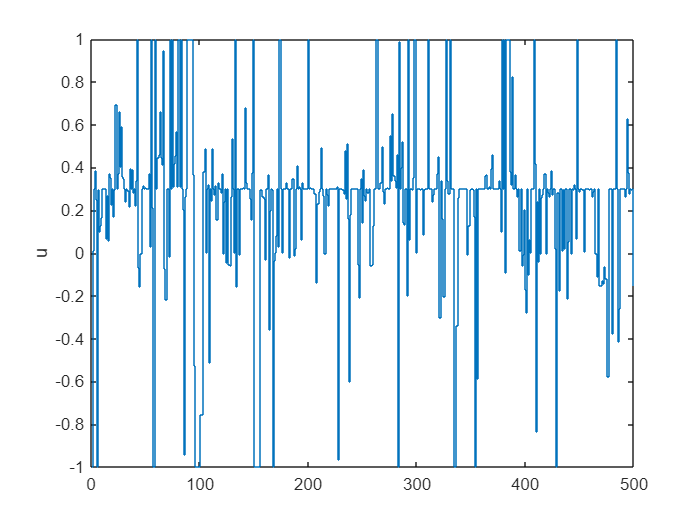


stairs(u)
ylabel('u')

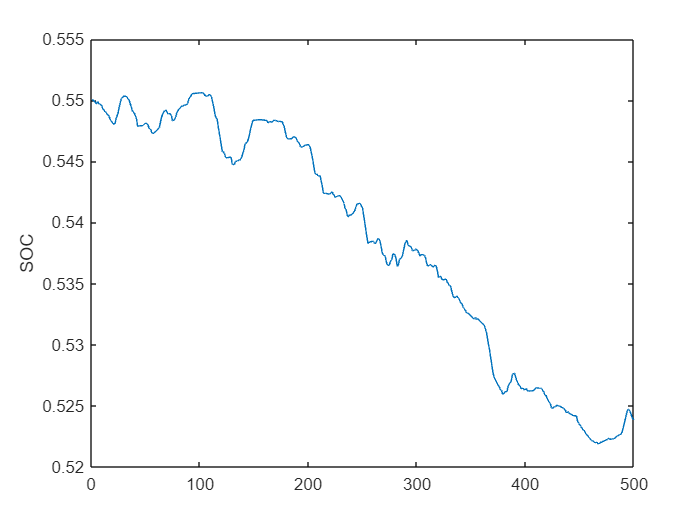

plot(SOC)
ylabel('SOC')

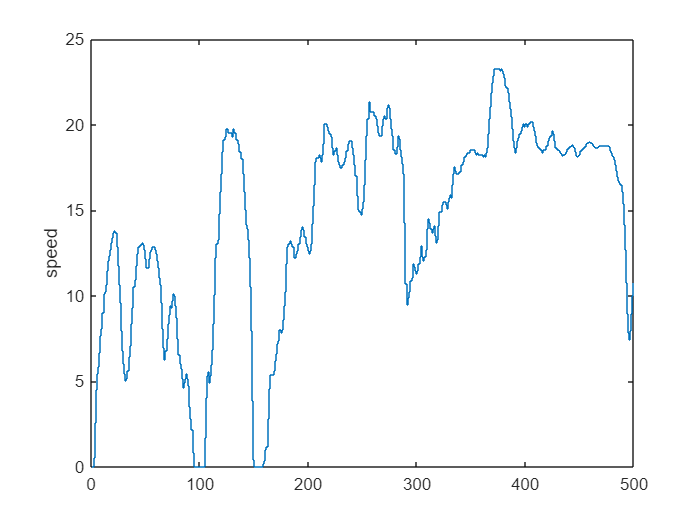

stairs(speed)
ylabel('speed')

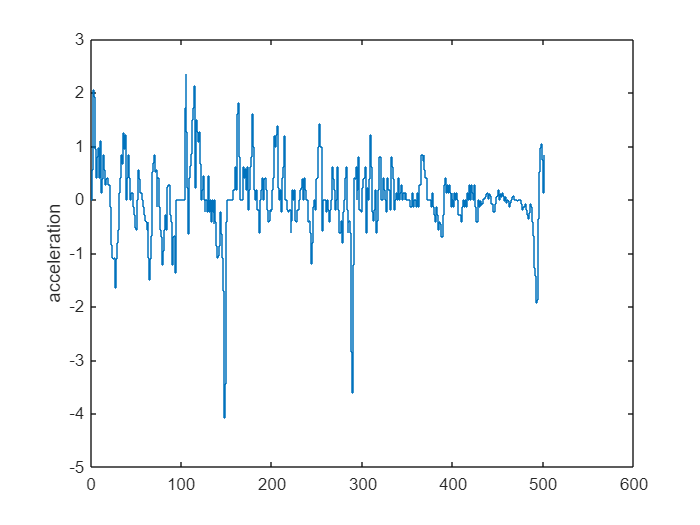

stairs(acceleration)
ylabel('acceleration')

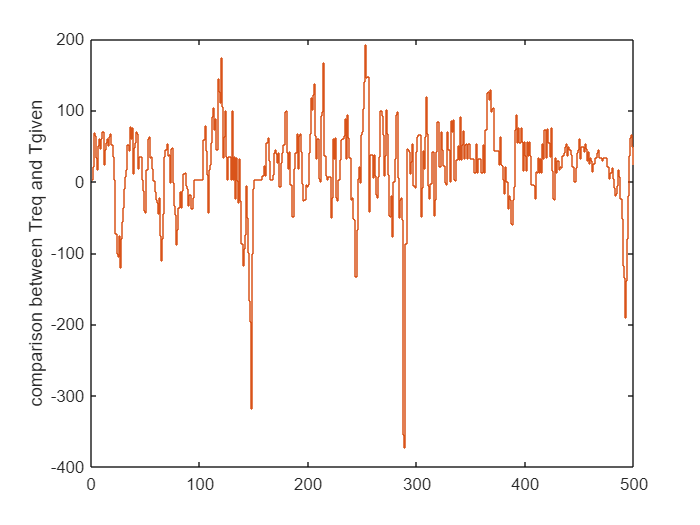

stairs(T_giv)
hold on
stairs(T_req)
hold off
ylabel('comparison between Treq and Tgiven')